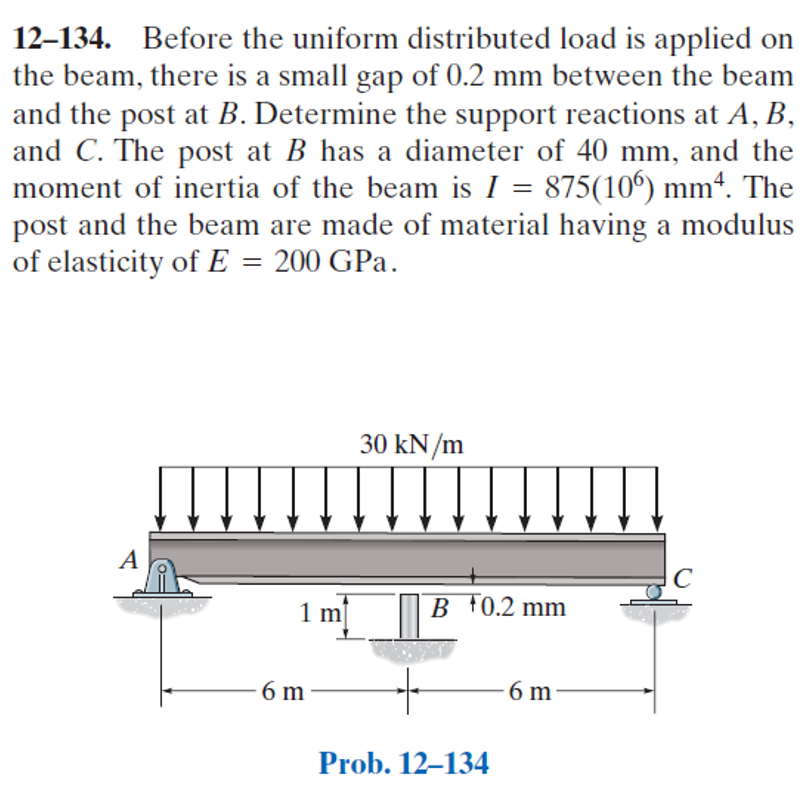

# beam

u = symunit;
b = beam;
b = b.add('reaction', 'force', 'Ra', 0);
b = b.add('reaction', 'force', 'Rb', 6*u.m);
b = b.add('reaction', 'force', 'Rc', 12*u.m);
b = b.add('distributed', 'force', -30*u.kN/u.m, [0 12]*u.m);
b.L = 12*u.m;

# section properties

b.E = rewrite(200*u.GPa, [u.kN u.m]);
b.I = rewrite(875e6*u.mm^4, u.m);

# elastic curve

[y dy m v w r] = b.elastic_curve([], 'factor'); %#ok
y

$$y(x) = \left\{ \begin{array}{cl} -\frac{x\,\left(x+3\,m\right)\,{\left(x-6\,m\right)}^{2}}{140000}\,\frac{1}{m^{3}} & \text{ if }x\leq 6\,m\\ -\frac{{\left(x-6\,m\right)}^{2}\,\left(x-12\,m\right)\,\left(x-15\,m\right)}{140000}\,\frac{1}{m^{3}} & \text{ if }6\,m<x \end{array}\right.$$

dy

$$dy(x) = \left\{ \begin{array}{cl} \frac{\left(x-6\,m\right)\,\left(-4\,x^{2}+3\,x\,m+18\,m^{2}\right)}{140000}\,\frac{1}{m^{3}} & \text{ if }x\leq 6\,m\\ -\frac{\left(x-6\,m\right)\,\left(4\,x^{2}-93\,x\,m+522\,m^{2}\right)}{140000}\,\frac{1}{m^{3}} & \text{ if }6\,m<x \end{array}\right.$$

m

$$m(x) = \left\{ \begin{array}{cl} -\frac{15\,x\,\left(2\,x-9\,m\right)}{2}\,\frac{\mathrm{kN}}{m} & \text{ if }x\leq 6\,m\\ -\frac{15\,\left(x-12\,m\right)\,\left(2\,x-15\,m\right)}{2}\,\frac{\mathrm{kN}}{m} & \text{ if }6\,m<x \end{array}\right.$$

v

$$v(x) = \left\{ \begin{array}{cl} -\frac{15\,\left(4\,x-9\,m\right)}{2}\,\frac{\mathrm{kN}}{m} & \text{ if }x\leq 6\,m\\ -\frac{15\,\left(4\,x-39\,m\right)}{2}\,\frac{\mathrm{kN}}{m} & \text{ if }6\,m<x \end{array}\right.$$

w

$$w(x) = -30\,\frac{\mathrm{kN}}{m}$$

addvar(y);

# reactions

Ra = r.Ra %#ok

$$Ra = \frac{135}{2}\,\mathrm{kN}$$

Rb = r.Rb %#ok

$$Rb = 225\,\mathrm{kN}$$

Rc = r.Rc %#ok

$$Rc = \frac{135}{2}\,\mathrm{kN}$$

clear Ra Rb Rc;

# shear and moment diagram

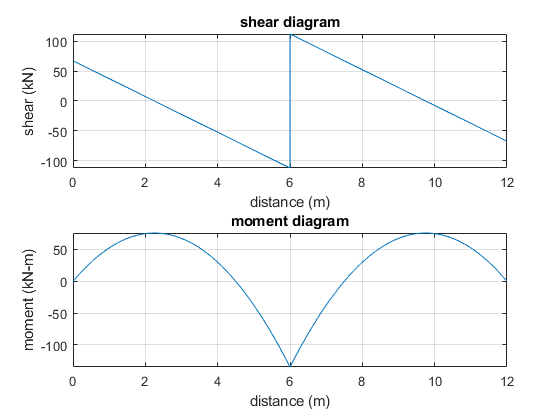

beam.shear_moment(m, v, [0 b.L], {'kN' 'm'});